clear;
clc;

qex = -200;
Fex = -1000;
Mex = 2000;

L = 0.12;
d1 = 0.03;
d2 = 0.02;
Es = 200e9;
J1 = pi * d1^4 / 64;
J2 = pi * d2^4 / 64;

N = 101;
x = linspace(0, 2*L, N);

K = zeros(2*N, 2*N);
b = zeros(2*N);

h = x(2) - x(1);
kpart = [
   12/h^3, 6/h^2, -12/h^3, 6/h^2;
   6/h^2, 4/h, -6/h^2, 2/h;
   -12/h^3, -6/h^2, 12/h^3, -6/h^2;
   6/h^2, 2/h, -6/h^2, 4/h
];
bpart = h * [1/2, h/12, 1/2, -h/12];

for k = 1:N-1
    if k <= (N-1)/2
        K(2*k-1:2*k+2, 2*k-1:2*k+2) = K(2*k-1:2*k+2, 2*k-1:2*k+2) + Es * J1 * kpart;
        b(2*k-1:2*k+2) = b(2*k-1:2*k+2) + qex * bpart;
    else
        K(2*k-1:2*k+2, 2*k-1:2*k+2) = K(2*k-1:2*k+2, 2*k-1:2*k+2) + Es * J2 * kpart;
    end
end

b(N) = b(N) + Fex;
b(2*N) = b(2*N) - Mex;

node_ID = [3:2*N-2, 2*N];
bm = b(node_ID);
Km = K(node_ID, node_ID);
res = zeros(2*N);
res(node_ID) = Km \ bm.';

w = res(1:2:2*N);
theta = res(2:2:2*N);

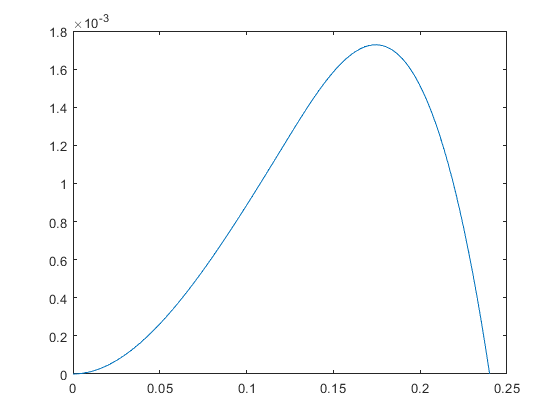

plot(x, w)
hold off;

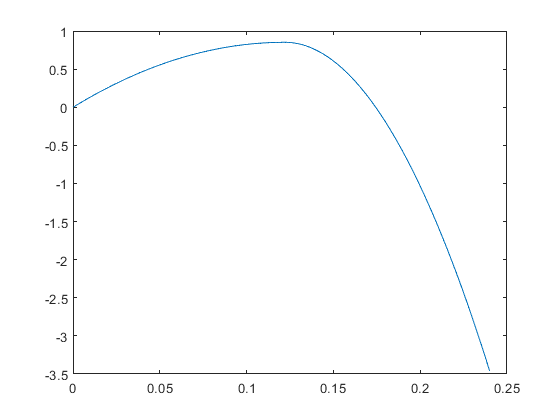

plot(x, theta*180/pi)